path = dir("G:\My Drive\1. Projects\PHYS-559 Graduate Laboratory (Spring 2023)\NMR Project\Final Paper Data\0.1498M\*.csv")

path = 25×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


sampleConcentration = '0.1498M'

sampleConcentration = '0.1498M'

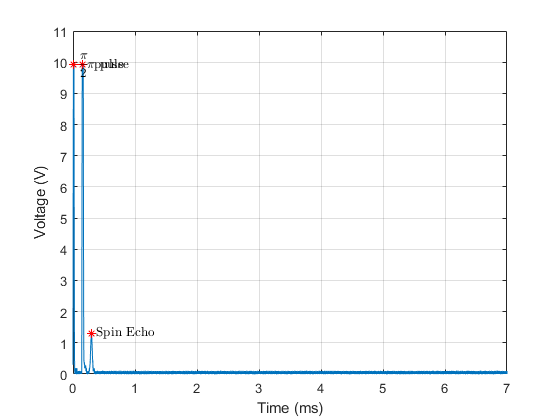

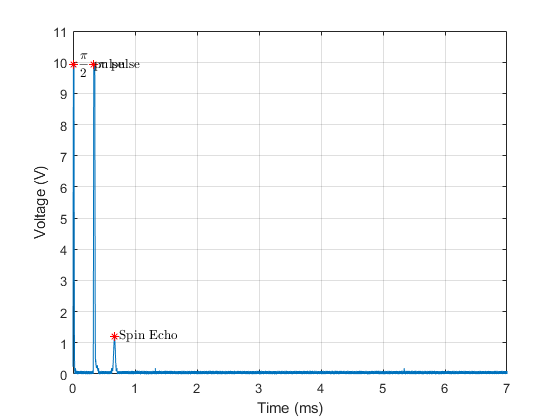

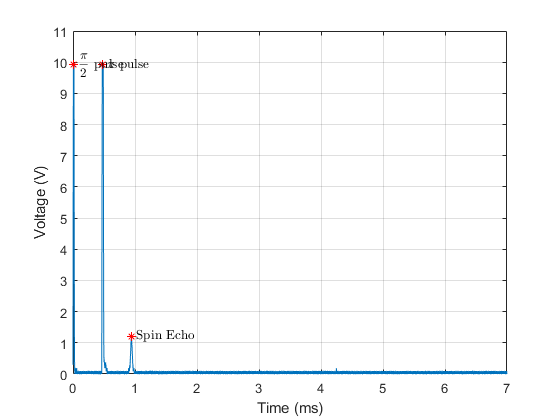

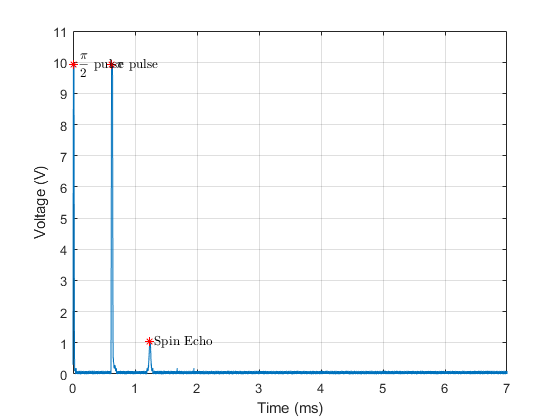

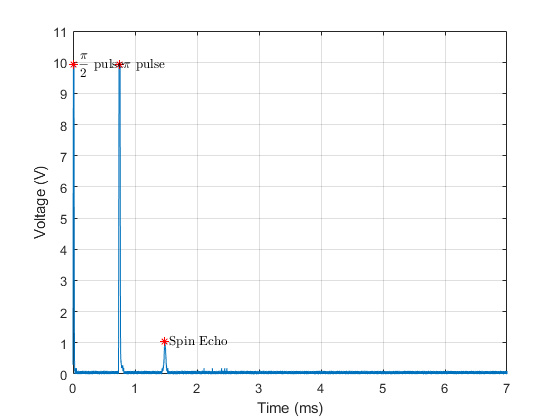

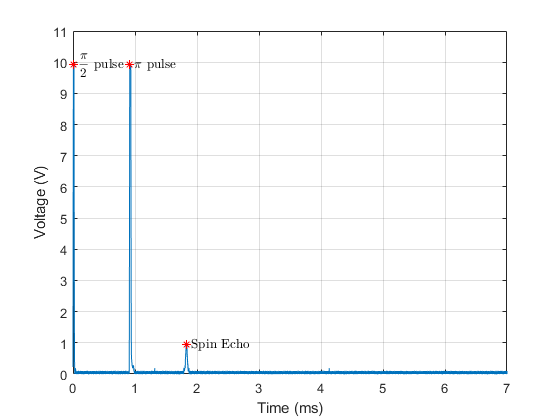

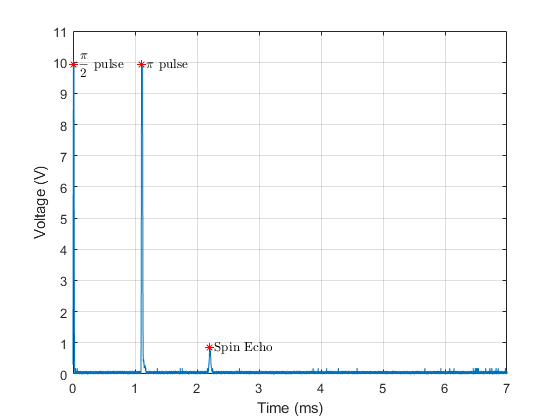

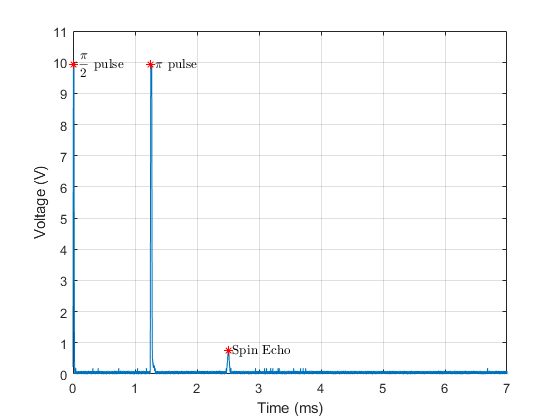

pulse_seperation =     0.1425    0.3286    0.4653    0.6147    0.7359    0.9088    1.0990    1.2472    1.4642    1.6895    1.8573    2.0672    2.2411    2.3968    2.5983    2.7216


spinEchoAmp =     1.3100    1.2165    1.2165    1.0292    1.0292    0.9357    0.8422    0.7486    0.6548    0.6548    0.5613    0.5613    0.5613    0.4678    0.4678    0.4678


[pulse_seperation, spinEchoAmp] = NMRdataAnalysis(path,sampleConcentration)

logSpinEchoAmp = log(spinEchoAmp)

logSpinEchoAmp =     0.2700    0.1960    0.1960    0.0287    0.0287   -0.0665   -0.1718   -0.2895   -0.4234   -0.4234   -0.5774   -0.5774   -0.5774   -0.7597   -0.7597   -0.7597


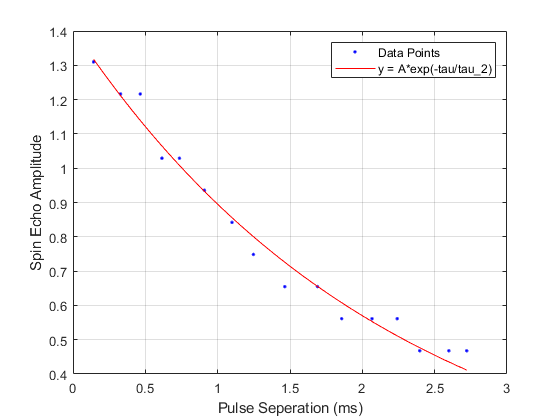

fitresult =      General model:
     fitresult(t) = A*exp(-t/t_2)
     Coefficients (with 95% confidence bounds):
       A =       1.405  (1.343, 1.467)
       t_2 =       2.216  (2.022, 2.41)

gof = struct with fields:
           sse: 0.0248
       rsquare: 0.9806
           dfe: 14
    adjrsquare: 0.9792
          rmse: 0.0421


[fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)

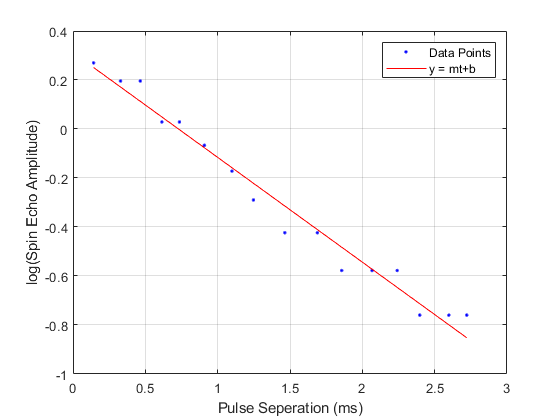

fitresult =      Linear model Poly1:
     fitresult(x) = p1*x + p2
       where x is normalized by mean 1.411 and std 0.8422
     Coefficients (with 95% confidence bounds):
       p1 =     -0.3602  (-0.394, -0.3263)
       p2 =     -0.2917  (-0.3244, -0.2589)

gof = struct with fields:
           sse: 0.0524
       rsquare: 0.9738
           dfe: 14
    adjrsquare: 0.9719
          rmse: 0.0612


[fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)

function [fitresult, gof] = exponentialFit(pulse_seperation, spinEchoAmp)
%CREATEFIT(PULSE_SEPERATION,SPINECHOAMP)
%  Create a fit.
%
%  Data for 'untitled fit 1' fit:
%      X Input : pulse_seperation
%      Y Output: spinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:36:59


%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( pulse_seperation, spinEchoAmp );

% Set up fittype and options.
ft = fittype( 'A*exp(-t/t_2)', 'independent', 't', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.0461713906311539 0.0971317812358475];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'Exponential Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = A*exp(-tau/tau_2)', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'Spin Echo Amplitude', 'Interpreter', 'none' );
grid on
end
function [fitresult, gof] = linearFit(pulse_seperation, logSpinEchoAmp)
%CREATEFIT1(PULSE_SEPERATION,LOGSPINECHOAMP)
%  Create a fit.
%
%  Data for 'Linear Fit' fit:
%      X Input : pulse_seperation
%      Y Output: logSpinEchoAmp
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 19-Feb-2023 22:39:47


%% Fit: 'Linear Fit'.
[xData, yData] = prepareCurveData( pulse_seperation, logSpinEchoAmp );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, 'Normalize', 'on' );

% Plot fit with data.
figure( 'Name', 'Linear Fit' );
h = plot( fitresult, xData, yData );
legend( h, 'Data Points', 'y = mt+b', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'Pulse Seperation (ms)', 'Interpreter', 'none' );
ylabel( 'log(Spin Echo Amplitude)', 'Interpreter', 'none' );
grid on
end

